## Tutorial 2: Context Module

In this tutorial you will learn about the context decoding tools included with BrainStat. The context decoding module consists of three parts: genetic decoding, meta-analytic decoding and histological comparisons. First, we'll consider how to run the genetic decoding analysis. But before we get started, please note that this tutorial, alike the previous one, requires that you have BrainStat and all its dependencies installed. For more details see our installation guide. Also, we'll run a simple linear model again like we did in the previous tutorial, as we'll be using the results of this model.

But first let us define our plot script 

% Ascertain script runs correctly both as live script and regular script.
run_as_live_script = true;
if run_as_live_script
    pretty = @pretty_plot;
else
    pretty = @(x)x;
end

and then we go into data loading and a first display

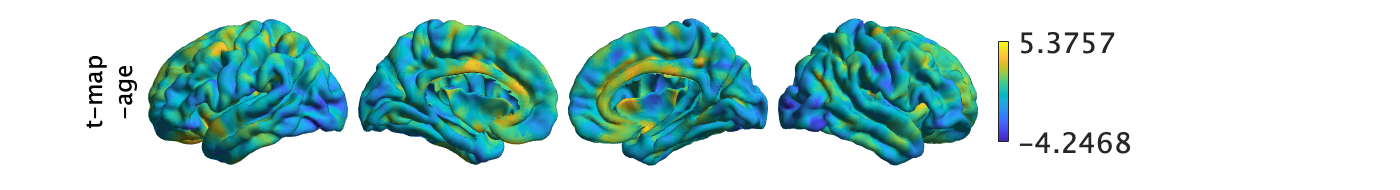

[cortical_thickness, demographics] = fetch_mics_data();
[surf_left, surf_right] = fetch_template_surface('fsaverage5');
mask = fetch_mask('fsaverage5');

term_age = FixedEffect(demographics.AGE_AT_SCAN, 'Age');
term_sex = FixedEffect(demographics.SEX);
term_subject = MixedEffect(demographics.SUB_ID);
model = term_age + term_sex + term_age * term_sex + term_subject;

contrast_age = -demographics.AGE_AT_SCAN;

slm = SLM( ...
   model, ...
   contrast_age, ...
   'surf', 'fsaverage5', ...
   'correction', {'rft', 'fdr'}, ...
   'mask', mask, ...
   'two_tailed', false, ...
   'cluster_threshold', 0.01);
slm.fit(cortical_thickness);

figure();
obj = plot_hemispheres(...
    slm.t',  ...
    {surf_left, surf_right}, ...
    'labeltext', {{'t-map', '-age'}} ...
    );
pretty(obj);

### Genetics

For genetic decoding we use the Allen Human Brain Atlas through the abagen toolbox. Note that, as abagen is only available in Python, we simply supply the genetic expression of pre-computed regions of interest with default parameters in the MATLAB toolbox. This should suffice for most use-cases, but for more specific use-cases we advise you to use the Python implementation of BrainStat. For a full list of supported parcellations see `help fetch_genetic_expression.`

[expression, gene_names] = surface_genetic_expression('schaefer', 100);

Reading atlas from file. This may take a few minutes.


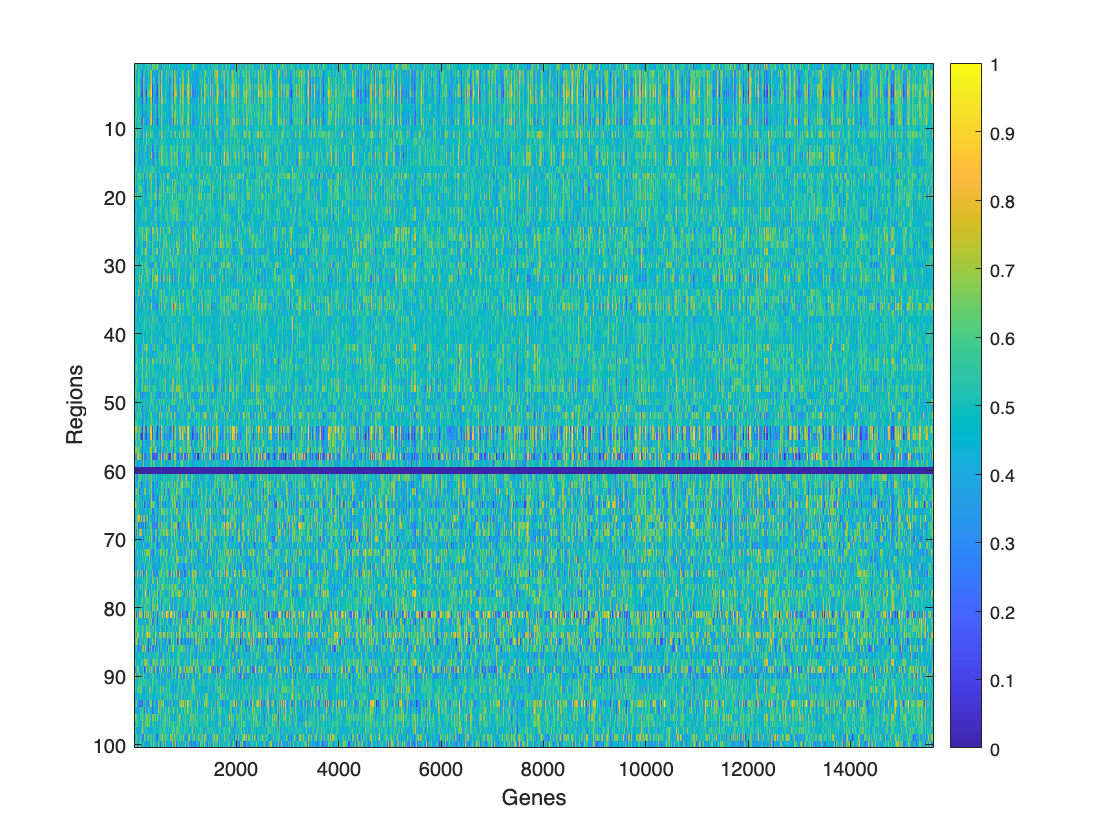

figure(); 
img = imagesc(expression);
xlabel('Genes');
ylabel('Regions');
colorbar;

The variable `expression` is a matrix containing the genetic expression of genes within each region of the atlas. These values will fall in the range [0, 1] where higher values represent higher expression. Some regions may return `NaN` values for all genes (e.g. see region 60 in the plot). This occurs when there are no samples within this region across all donors. The variable `gene_names` contains the names of each gene in the same order as the columns of `expression`. We can also correlate these genes to the t-statistic map derived earlier. Let's do this for the highest correlating gene, WFDC1, and create a scatter plot as well as a surface map.

schaefer_100 = fetch_parcellation('fsaverage5', 'schaefer', 100); 

Reading from version 2
colortable with 51 entries read (originally Schaefer2018_100Parcels_7Networks)
Reading from version 2
colortable with 51 entries read (originally Schaefer2018_100Parcels_7Networks)


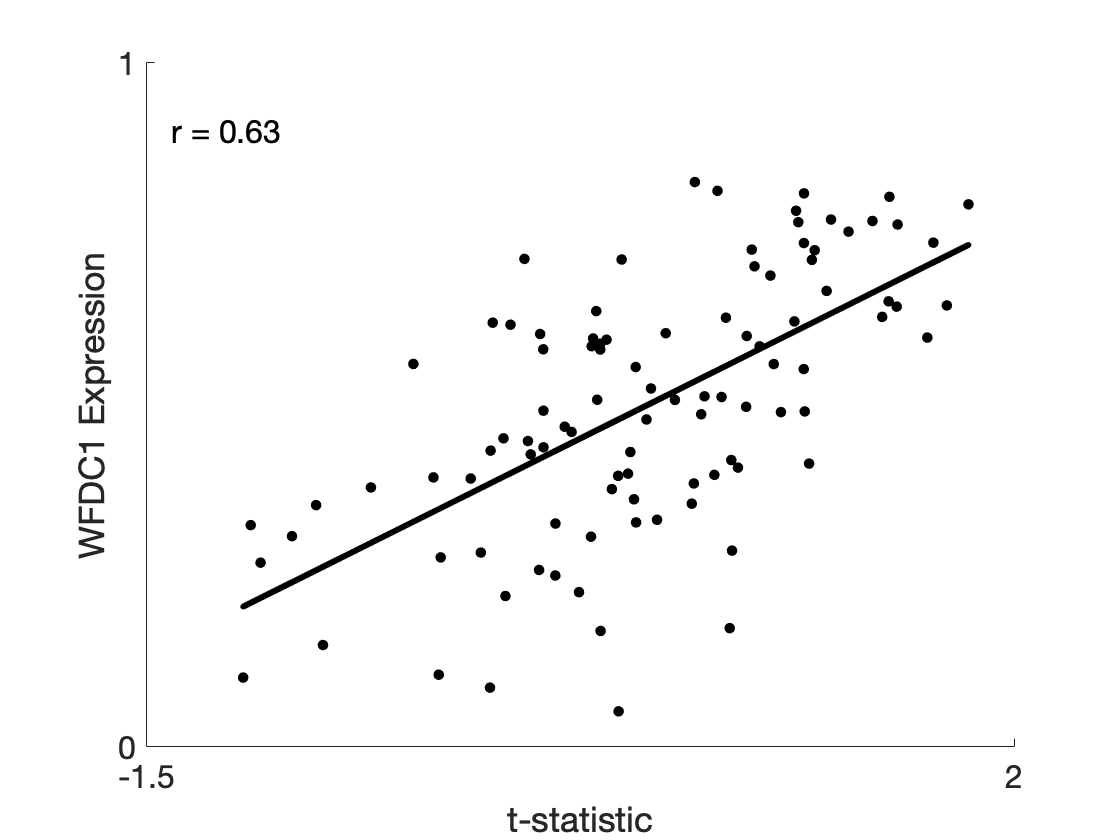

t_schaefer_100 = full2parcel(slm.t, schaefer_100);

WFDC1_expression = expression(:, gene_names == "WFDC1");
no_nan = ~isnan(WFDC1_expression);
t_WFDC1_corr = corr(t_schaefer_100(no_nan), WFDC1_expression(no_nan));

bestfit_coefficients = polyfit(t_schaefer_100(no_nan), ...
    WFDC1_expression(no_nan), 1);

figure();
scatter(t_schaefer_100, WFDC1_expression, 200, 'k', '.');
hold on
plot(t_schaefer_100, polyval(bestfit_coefficients, t_schaefer_100), ...
    'k', 'LineWidth', 3);
xlabel('t-statistic')
ylabel('WFDC1 Expression')
set(gca, 'FontSize', 16, 'YLim', [0, 1], 'YTick', [0, 1], ...
    'Xtick', [-1.5, 2])
text(-1.4, 0.9, sprintf('r = %0.2f', t_WFDC1_corr), 'FontSize', 16);

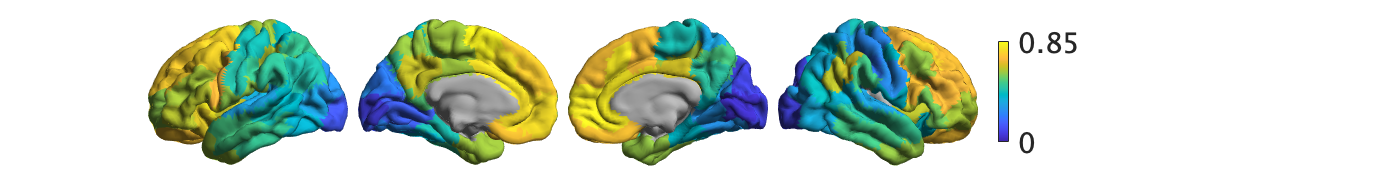

WFDC1_expression(isnan(WFDC1_expression)) = -inf;
figure();
obj = plot_hemispheres(WFDC1_expression, {surf_left, surf_right}, ...
    'parcellation', schaefer_100);
obj.colormaps([.7 .7 .7; parula])
obj.colorlimits([0, 0.85])
pretty_plot(obj)

We find a small correlation. To test for significance between two parcellated brain maps, we can use spin permutation tests from the ENIGMA Toolbox. An example of spin permutation tests between vertexwise maps (using BrainSpace) is shown further down in the tutorial.

% Replace -Inf with NaN
WFDC1_expression_noInf = WFDC1_expression;
WFDC1_expression_noInf(isinf(WFDC1_expression_noInf)) = nan;

% Spin permutation testing for two cortical maps
[spin_p, spin_d] = spin_test(t_schaefer_100, WFDC1_expression_noInf, 'surface_name', ...
                             'fsa5', 'parcellation_name', 'schaefer_100', ...
                             'n_rot', 1000, 'type', 'pearson');

Reading from version 2
colortable with 51 entries read (originally Schaefer2018_100Parcels_7Networks)
Reading from version 2
colortable with 51 entries read (originally Schaefer2018_100Parcels_7Networks)
permutation 100 of 1000
permutation 200 of 1000
permutation 300 of 1000
permutation 400 of 1000
permutation 500 of 1000
permutation 600 of 1000
permutation 700 of 1000
permutation 800 of 1000
map to itself n.1
permutation 900 of 1000
permutation 1000 of 1000


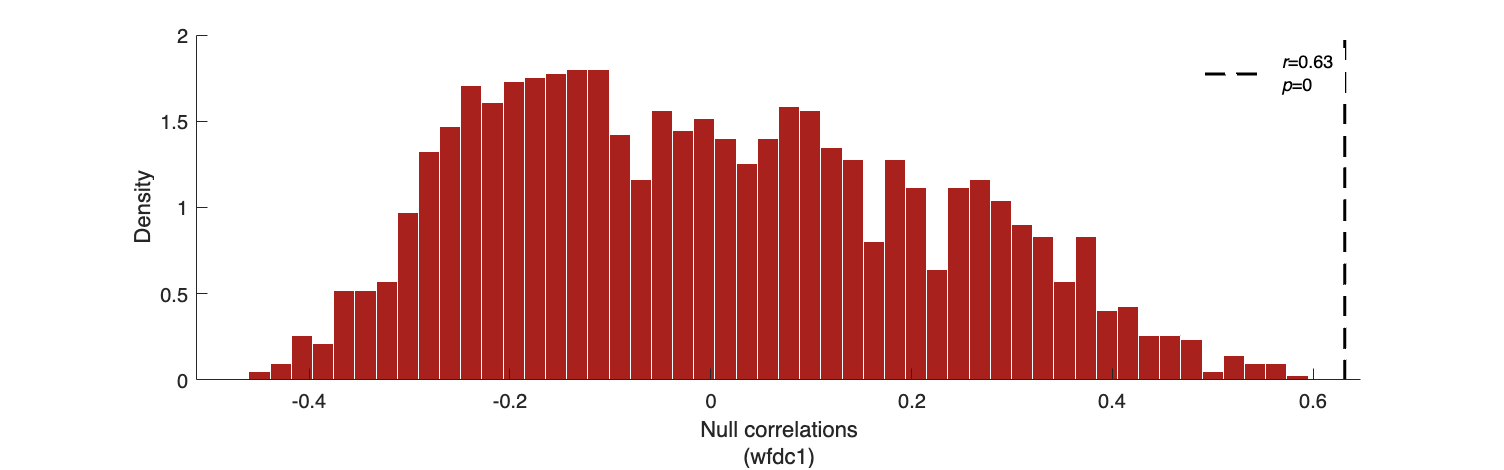


% Store p-value and null distribution
p_and_d = cell2struct({[spin_p; spin_d]}, {'wfdc1'}, 2);

% Plot null distribution
f = figure;

    set(gcf,'color','w');
    set(gcf,'units','normalized','position',[0 0 1 0.5])
    fns = fieldnames(p_and_d);

    % Define plot colors
    col = [0.66 0.13 0.11];

    % Plot null distributions
    h = histogram(p_and_d.(fns{1})(2:end), 50, 'Normalization', 'pdf', 'edgecolor', 'w', ...
                  'facecolor', col, 'facealpha', 1, 'linewidth', 0.5);
    l = line([t_WFDC1_corr t_WFDC1_corr], get(gca, 'ylim'), 'linestyle', '--', ...
             'color', 'k', 'linewidth', 1.5);
    xlabel(['Null correlations' newline '(' strrep(fns{1}, '_', ' ') ')'])
    ylabel('Density')
    legend(l,['{\it r}=' num2str(round(t_WFDC1_corr, 2)) newline ...
              '{\it p}=' num2str(round(p_and_d.(fns{1})(1), 3))])
    legend boxoff
    set(gca, 'box', 'off')

### `Meta-Analytic Decoding`

To perform meta-analytic decoding, BrainStat uses precomputed Neurosynth maps. Here we test which terms are most associated with our t-statistic map. The surface decoder interpolates the data from the surface to the voxels in the volume that are in between pial and white matter surface. Next, using all voxels that are non-zero both in this volume and in the Neurosynth database, a Pearson correlation is computed for every feature. Please be aware that this analysis may take several minutes to download and run.

[correlation, feature] = meta_analytic_decoder(slm.t, ...
    'template', 'fsaverage5');
disp(correlation(1:3));

    0.2072
    0.2070
    0.2003



disp(feature(1:3));

    {'nucleus accumbens'}    {'accumbens'}    {'dorsal anterior'}



The variable correlation now contains the correlation values between the t-statistic map and each of the neurosynth features. The corresponding feature names are stored in the variable feature. An easy way of visualizing this data is by using a word cloud. These are simple to build with MATLAB:

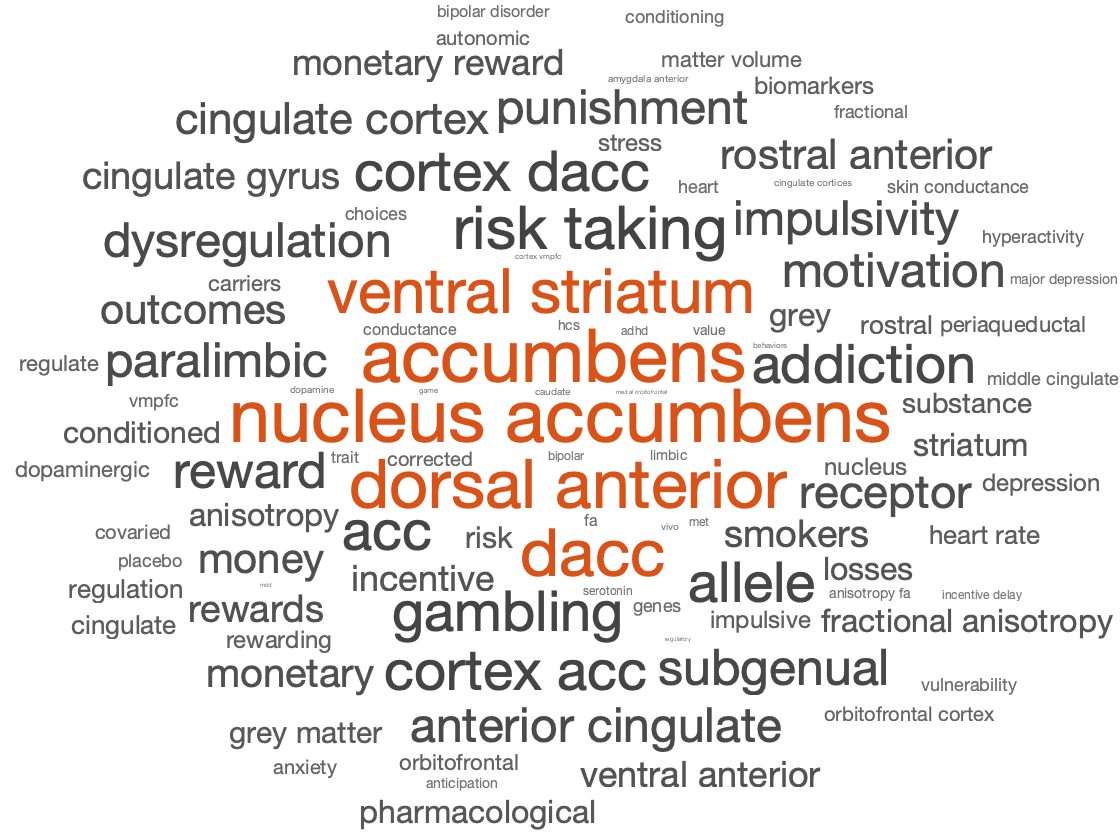

figure();
wc = wordcloud(feature(correlation>0), correlation(correlation>0));

Here, larger words represent higher correlations. It's common to see the largest words be related to anatomy. Looking past anatomical terms, we see several words related to motivation and risk taking behavior e.g. reward, motivation, additction, gambling, punishment.

Alternatively, we can visualize the top correlation values and associated terms in a radar plot, as follows:

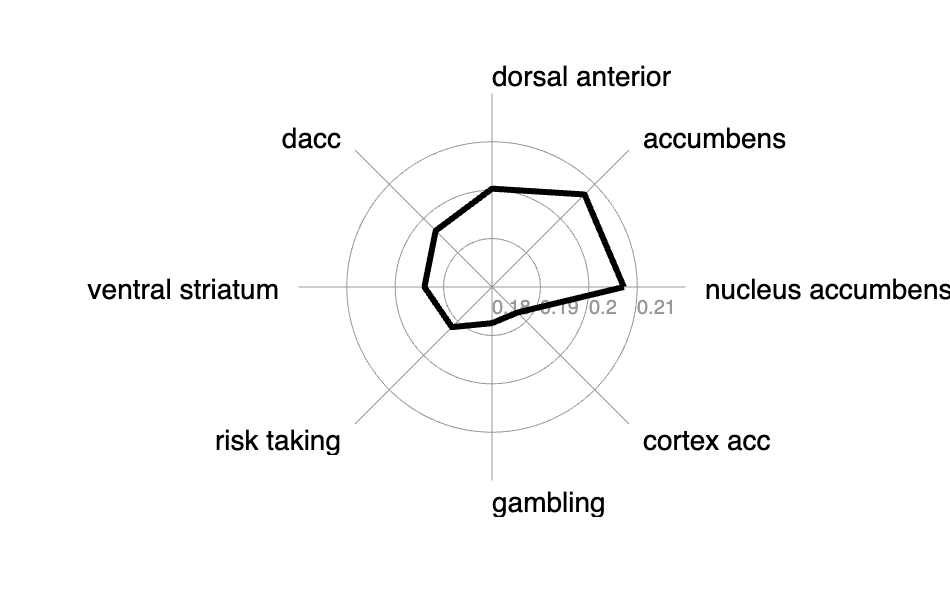

numFeat = 8;
data = correlation(1:numFeat);
label = feature(1:numFeat);
radar_plot(data, 'label', label, 'axis_range', [0.18 0.22]);

### Histology

For histological decoding we use microstructural profile covariance gradients, as first shown by [(Paquola et al, 2019, Plos Biology)](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.3000284),  computed from the BigBrain dataset. Firstly, lets download the MPC data and compute its gradients.

schaefer_400 = fetch_parcellation('fsaverage5' ,'schaefer', 400);

Reading from version 2
colortable with 201 entries read (originally Schaefer2018_400Parcels_7Networks)
Reading from version 2
colortable with 201 entries read (originally Schaefer2018_400Parcels_7Networks)



histology_profiles = read_histology_profile('template', 'fsaverage5');
mpc = compute_mpc(histology_profiles, schaefer_400);

Sorting data by smallest to largest number in the label! (labelmean.m)


gm = compute_histology_gradients(mpc);

The variable `profiles` now contains histological profiles sampled at 50 different depths across the cortex, `mpc` contains the covariance of these profiles, and `gm` contains their gradients. Depending on your use-case, each of these variables could be of interest, but for purposes of this tutorial we'll  plot the gradients to the surface with BrainSpace. For details on what the GradientMaps class, `gm`, contains please consult the BrainSpace documentation.

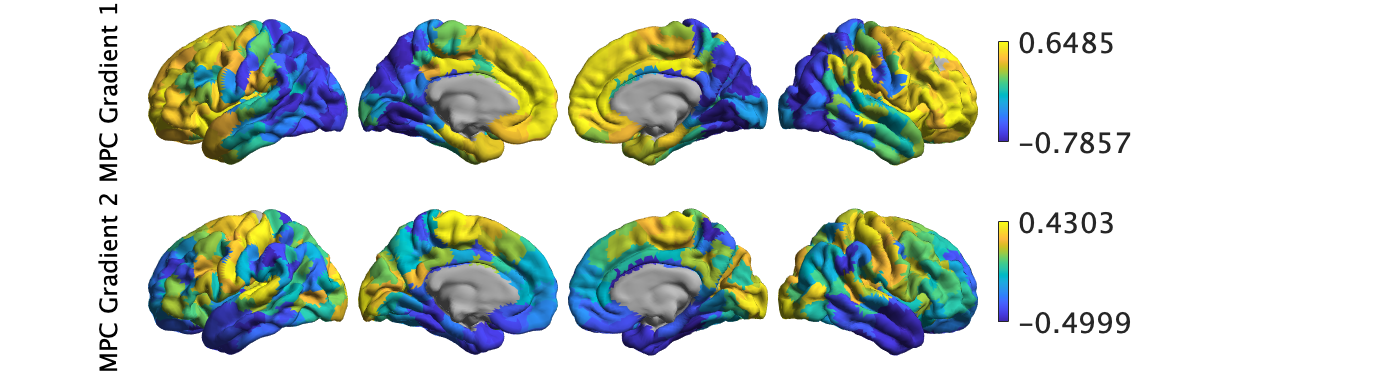

vertexwise_gradients = parcel2full(gm.gradients{1}(:,1:2), schaefer_400);
vertexwise_gradients(isnan(vertexwise_gradients)) = inf; 

obj = plot_hemispheres(vertexwise_gradients, ...
    {surf_left, surf_right}, ...
    'labeltext', {'MPC Gradient 1', 'MPC Gradient 2'});
obj.colormaps([parula; .7 .7 .7])
pretty_plot(obj);

Note that we no longer use the y-axis regression used in [(Paquola et al., 2019, Plos Biology)](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.3000284), as such the first gradient becomes an anterior-posterior- gradient. Next, lets plot a scatter plot between our t-statistic map and the first gradient of MPC.

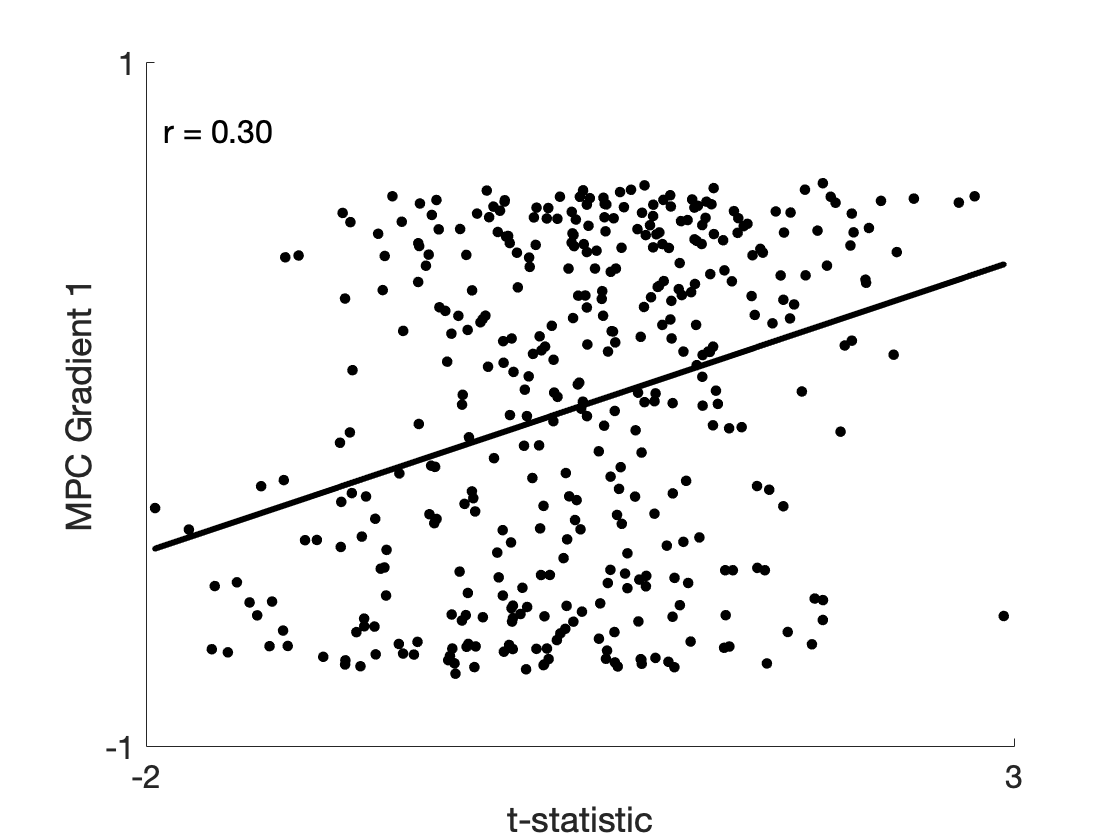

t_schaefer_400 = full2parcel(slm.t, schaefer_400);
t_mpc_corr = corr(t_schaefer_400, gm.gradients{1}(:,1));

bestfit_coefficients = polyfit(t_schaefer_400, gm.gradients{1}(:,1), 1);

figure();
scatter(t_schaefer_400, gm.gradients{1}(:,1), 200, 'k', '.');
hold on
plot(t_schaefer_400, polyval(bestfit_coefficients, t_schaefer_400), ...
    'k', 'LineWidth', 3);
xlabel('t-statistic')
ylabel('MPC Gradient 1')
set(gca, 'FontSize', 16, 'YLim', [-1, 1], 'YTick', [-1, 1], ...
    'Xtick', [-2, 3], 'XLim', [-2, 3])
text(-1.9, 0.8, sprintf('r = %0.2f', t_mpc_corr), 'FontSize', 16)

### Resting-State Contextualization

Lastly, BrainStat provides contextualization using resting-state fMRI markers: specifically, with the Yeo functional networks [(Yeo et al., 2011, Journal of Neurophysiology)](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3174820/), a clustering of resting-state connectivity, and the functional gradients [(Margulies et al., 2016, PNAS)](https://www.pnas.org/content/113/44/12574), a lower dimensional manifold of resting-state connectivity. 

Lets first have a look at contextualization of our t-statistic map using their mean within the Yeo networks. 

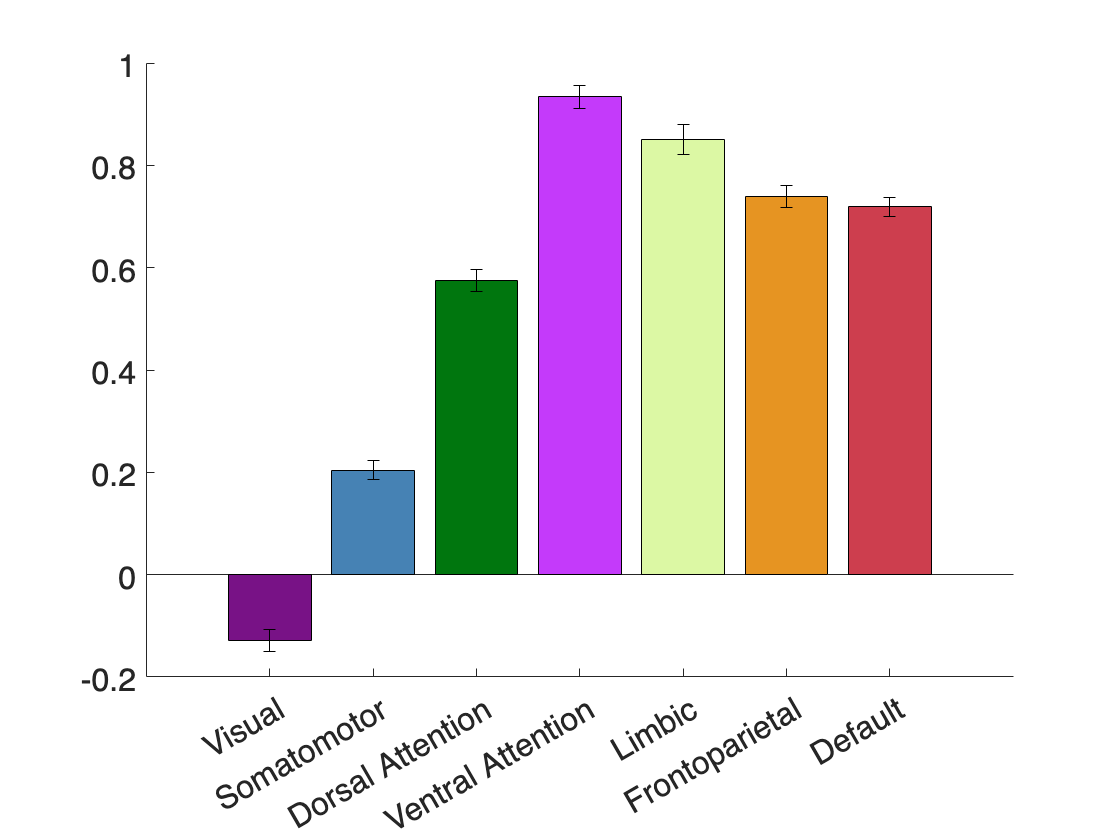

% Get mean/sem t-stat within yeo networks
compute_sem = @(x) std(x, 'omitnan') / sqrt(sum(~isnan(x)));

mean_t_stat = yeo_networks_association(slm.t, ...
    'template', 'fsaverage5');
sem_t_stat = yeo_networks_association(slm.t, ...
    'template', 'fsaverage5', 'reduction_operation', compute_sem);
[network_names, colormap] = fetch_yeo_networks_metadata(7);

% Create a t-statistic bar plot for the Yeo networks. 
figure;
axes('XTick', 1:7, 'XTickLabel', network_names, 'FontSize', 16);
hold on
bar(mean_t_stat, 'FaceColor', 'flat', 'CData', colormap);
errorbar(1:numel(mean_t_stat), mean_t_stat, sem_t_stat, sem_t_stat, ...
    'Color', 'k', 'LineStyle', 'None');

Here we can see that the effects are largest in the ventral attention and limbic networks, and that the visual network is the only region with a negative t-statistic.

Next, lets have a look at how cortical thickness relates to the first functional gradient which describes a sensory-transmodal axis in the brain. First lets plot the first few gradients and a scatter plot of the t-statistic map versus the first gradient.

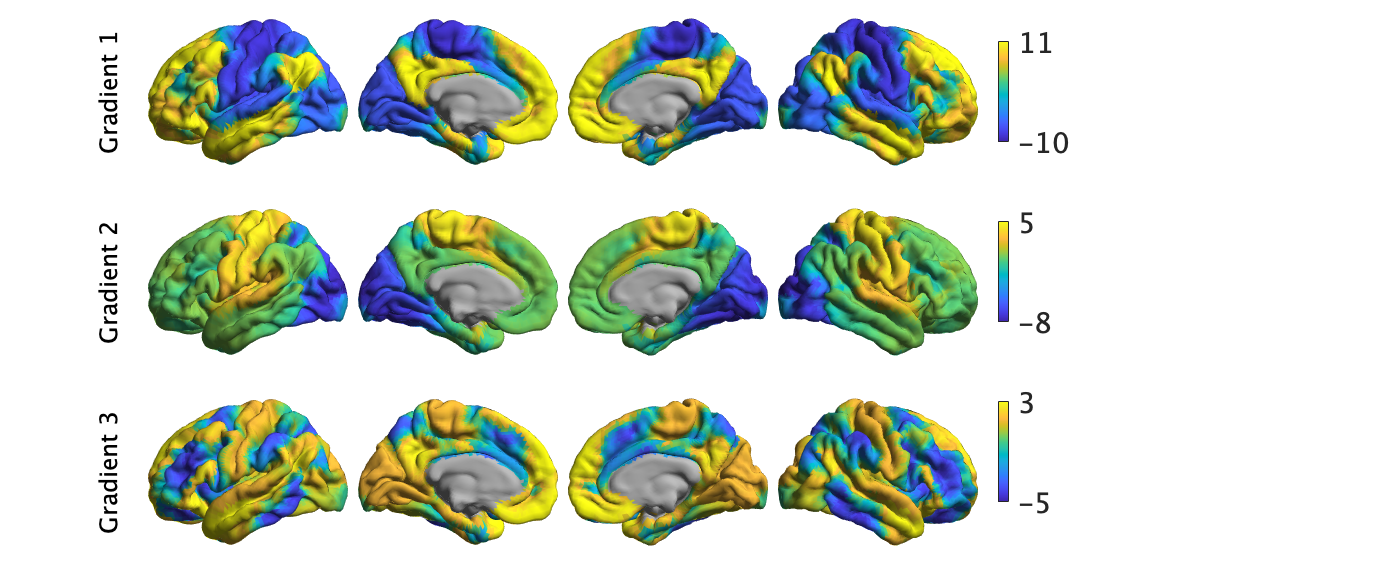

functional_gradients = fetch_gradients('fsaverage5', 'margulies2016');
gradients_plot = functional_gradients;
gradients_plot(isnan(gradients_plot)) = -inf;

% Plot the gradients on the surface.
obj = plot_hemispheres(...
    gradients_plot(:,1:3), ...
    {surf_left, surf_right}, ...
    'LabelText', "Gradient " + (1:3));

obj.colormaps([.7 .7 .7; parula])
obj.colorlimits([-10, 11; -8, 5; -5, 3])

pretty_plot(obj)

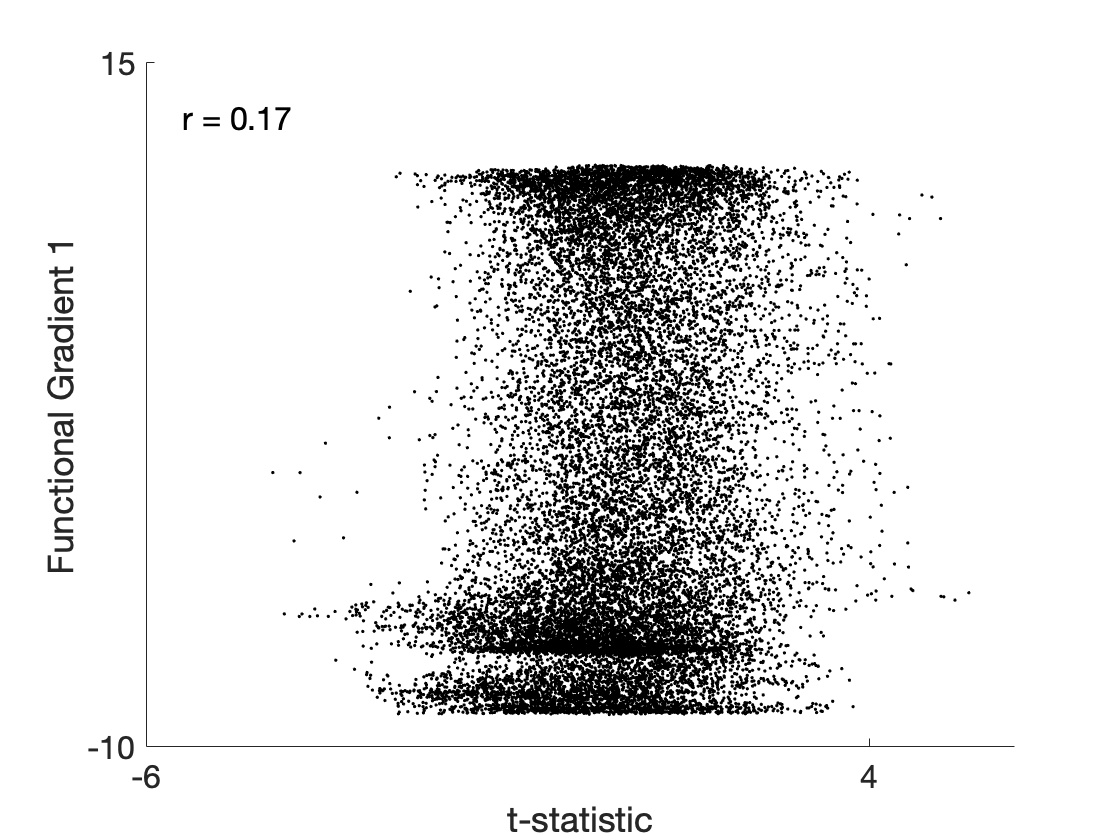

% Plot a scatter plot
figure();
coefficients = polyfit(slm.t(mask), functional_gradients(mask, 1), 1);
no_nan = ~isnan(slm.t)' & ~isnan(functional_gradients(:,1));
r = corr(slm.t(no_nan)', functional_gradients(no_nan, 1));

scatter(slm.t(no_nan), functional_gradients(no_nan, 1), 10, 'k', '.');
hold on
plot(slm.t(no_nan), polyval(coefficients, slm.t(no_nan)), ...
    'k', 'LineWidth', 3);
xlabel('t-statistic')
ylabel('Functional Gradient 1')
set(gca, 'FontSize', 16, 'YLim', [-10, 15], 'YTick', [-10, 15], ...
    'Xtick', [-6, 4])
text(-5.5, 13, sprintf('r = %0.2f', r), 'FontSize', 16)

It seems the correlations are quite low. However, we'll need some more complex tests to assess statistical significance. There are many ways to compare these gradients to cortical markers. In general, we recommend using corrections for spatial autocorrelation which are implemented in the ENIGMA Toolbox (for parcellated brain maps; see example above) or BrainSpace (for vertexwise maps; see example below).

In a spin test we compare the empirical correlation between the gradient and the cortical marker to a distribution of correlations derived from data rotated across the cortical surface. The p-value then depends on the percentile of the empirical correlation within the permuted distribution.

[sphere_left, sphere_right] = fetch_template_surface('fsaverage5', ...
    'layer', 'sphere');
t_left = slm.t(1:end/2)';
t_right = slm.t(end/2+1:end)';

% Note: for the tutorial we run only 100 permutations.
% We generally recommend at least 1000.
t_permuted = spin_permutations( ...
    {t_left, t_right}, ...
    {sphere_left, sphere_right}, 100, ...
    'random_state', 2021); 

Running Spin Permutation


t_permuted_full = squeeze([t_permuted{1}; t_permuted{2}]);
r_empirical = corr(slm.t', functional_gradients(:, 1), ...
    'rows', 'pairwise');
r_permuted = corr(t_permuted_full, functional_gradients(:, 1), ...
    'rows', 'pairwise');

% Significance depends on whether we do a one-tailed or two-tailed test.
% If one-tailed it depends on in which direction the test is. 
p_value_right_tailed = mean(r_empirical > r_permuted);
p_value_left_tailed = mean(r_empirical < r_permuted);
p_value_two_tailed = min(p_value_right_tailed, p_value_left_tailed) * 2; 

fprintf(['The two-tailed p-value between our t-statistic map ' ...
    'and \ngradient 1 is %0.2g.\n'], ...
    p_value_two_tailed);

The two-tailed p-value between our t-statistic map and 
gradient 1 is 0.1.


## Decoding without statistics module - mean thickness

It is fully possible to also run context decoding on maps that do not per se come from the statistics module of brainstat. In example below, we decode the mean cortical thickness map of our participants

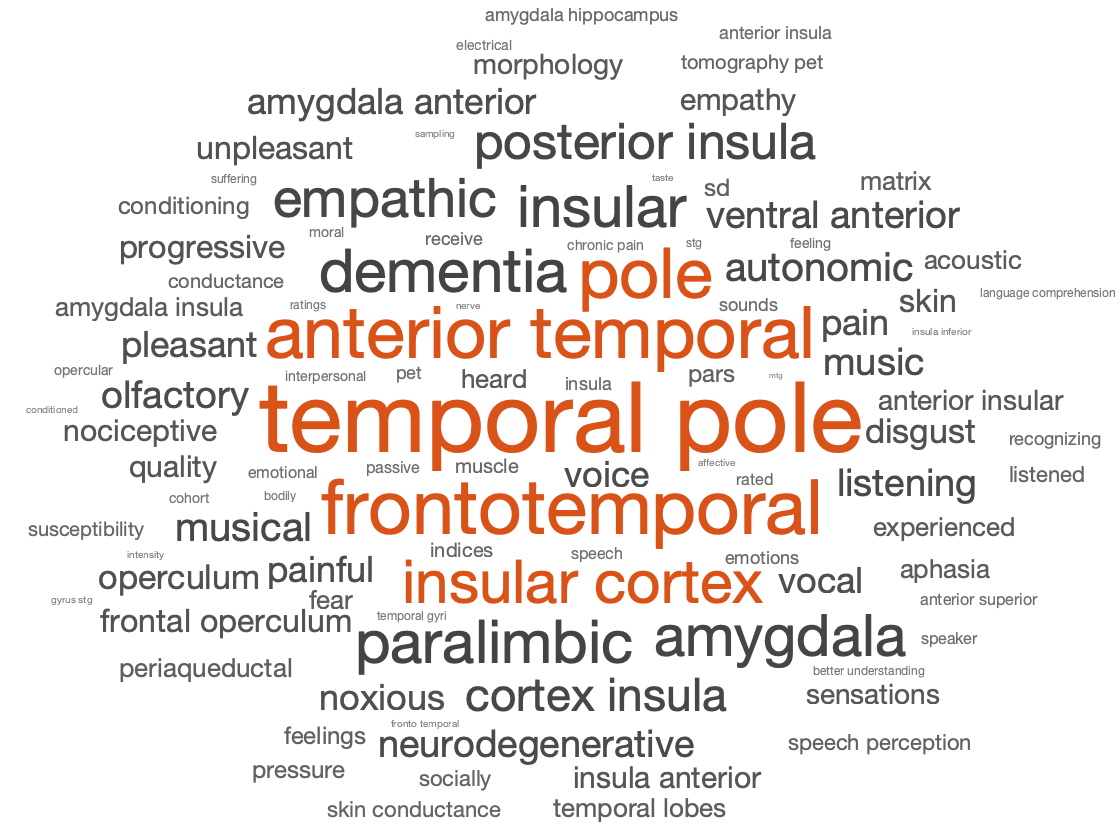

[correlation, feature] = meta_analytic_decoder(mean(cortical_thickness,1), ...
    'template', 'fsaverage5');
figure();
wc = wordcloud(feature(correlation>0), correlation(correlation>0));

## Decoding without statistics module - decoding matlab stats results

It is equally possible to run context decoding on maps derived from other tools. In the example below, we decode results from Matlab's build in t-tests

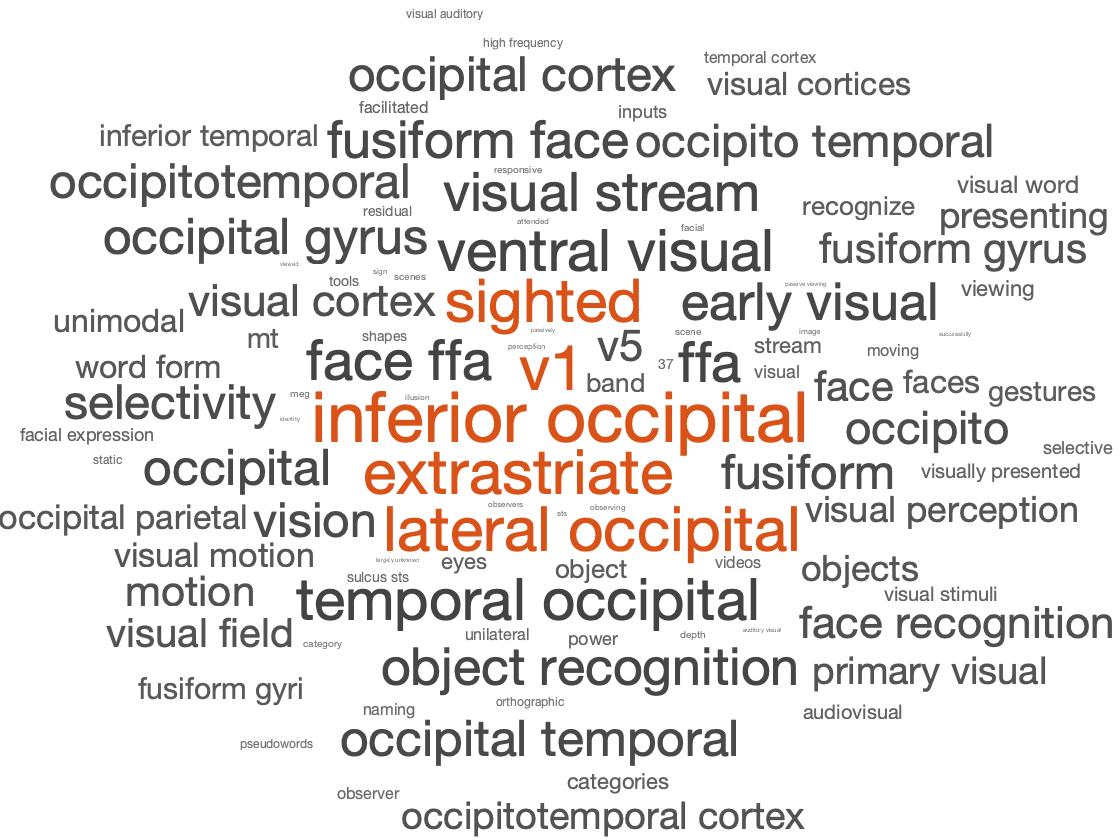

A = demographics.AGE_AT_SCAN; 
X = cortical_thickness(A>median(A),:);
Y = cortical_thickness(A<=(median(A)-1),:);
[h,p,ci,stats] = ttest2(X,Y);

[correlation, feature] = meta_analytic_decoder(stats.tstat, ...
    'template', 'fsaverage5');
figure();
wc = wordcloud(feature(correlation>0), correlation(correlation>0));

That concludes the tutorials of BrainStat. If anything is unclear, or if you think you've found a bug, please post it to the [Issues page of our Github](https://github.com/MICA-MNI/BrainStat/issues). 

Happy BrainStating!

function pretty_plot(obj)
    % Makes the BrainSpace plots prettier inside live scripts. 
    obj.handles.figure.Units = 'pixels';
    set(obj.handles.axes, 'Units', 'pixels')
    set(obj.handles.colorbar, 'Units', 'pixels');
    obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
    set(obj.handles.text, 'FontSize', 12);
    
    for jj = 1:size(obj.data, 2) % variates
        obj.handles.colorbar(jj).Position = [...
            500, ...
            30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
            5, ...
            50];
        for ii = 1:4 % views
            obj.handles.axes(jj, ii).Position = [...
                75 + (ii-1)*105, ...
                (size(obj.data, 2) * 95) - jj*95, ...
                100, ...
                100];
        end
    end
end